The functions were tested on MATLAB 2019b and 2022b.

%% set parameters
N_cell = 100; % number of cells in the system
radius = 1; % the radius of cell, i.e. l in the paper
phi = 0.5; % packing fraction
P0 = 4.8;
A0 = pi;
tension_difference = 0.2; % \Lambda in the paper
box_size = sqrt(N_cell*pi/phi); % box_size could be a scalar L, or a 1x2 vector [Lx, Ly] 
delta_t = 0.01;

% Parameters for tissue energy, see Eq. (3) in the paper
K_P = 1*ones(N_cell, 1); 
A0_list = A0*ones(N_cell, 1);
P0_list = P0*ones(N_cell, 1);

% set random seed for this demo
rng(3);

% initial the cell center positions in the center of the box
center_xy = ((rand(N_cell, 2)-0.5)*0.3+0.5)*box_size;

First, run molecular dynamics simulation for 30 unit time with zero motility (v0=0) to reach a steady state, store the cell center positions in center_xy_zero_motility. This relaxation takes ~3 min on my laptop.

tic;
for time = 0:delta_t:30
    % generate finite Voronoi configuration
    [cell_chain, edgelist, vertex_position, area_list, perimeter_list] = ...
                make_finite_voronoi_pbc(center_xy, radius, box_size);
    % calculate the interaction force
    center_force = get_finite_voronoi_force(center_xy, cell_chain, edgelist, ...
					vertex_position, radius, ones(N_cell, 1), ...
                                        A0_list, K_P, P0_list, tension_difference, ...
                                        area_list, perimeter_list, box_size);
    % update cell center positions
    center_xy = mod(center_xy + center_force*delta_t, box_size);
          
end
toc

Elapsed time is 190.638782 seconds.


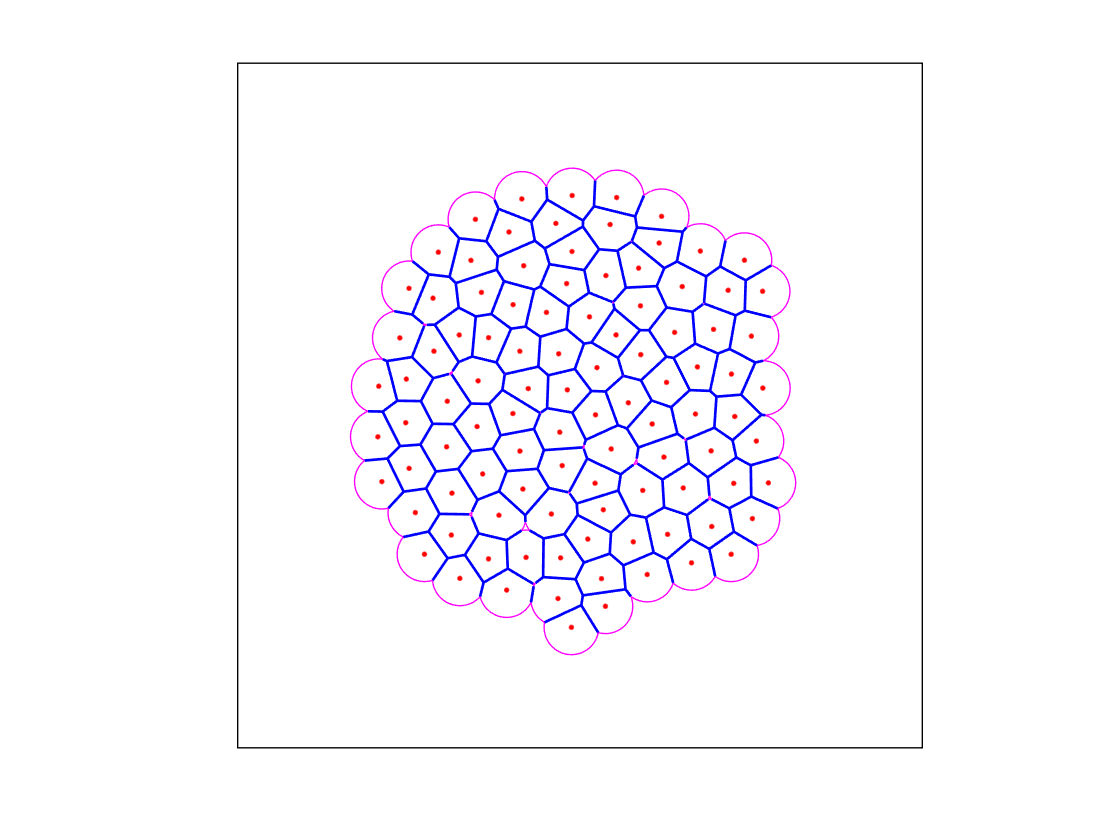

figure, hold on, axis off
draw_finite_voronoi(cell_chain, edgelist, vertex_position, ...
                    box_size, center_xy, radius)

center_xy_zero_motility = center_xy;

Then we run two simulations with v0=1.2 and v0=2.4 for 10 unit time, respectively, and plot the final snapshots accordingly.

Elapsed time is 78.161163 seconds.


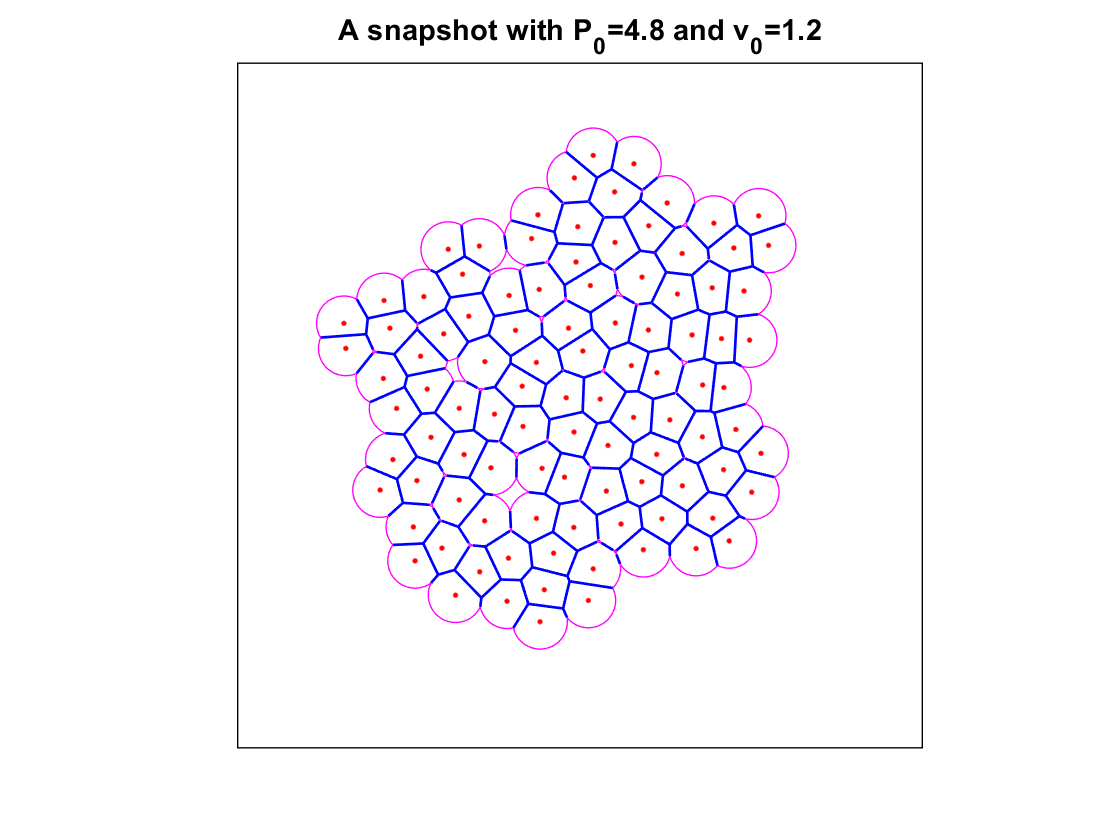

Elapsed time is 77.234963 seconds.


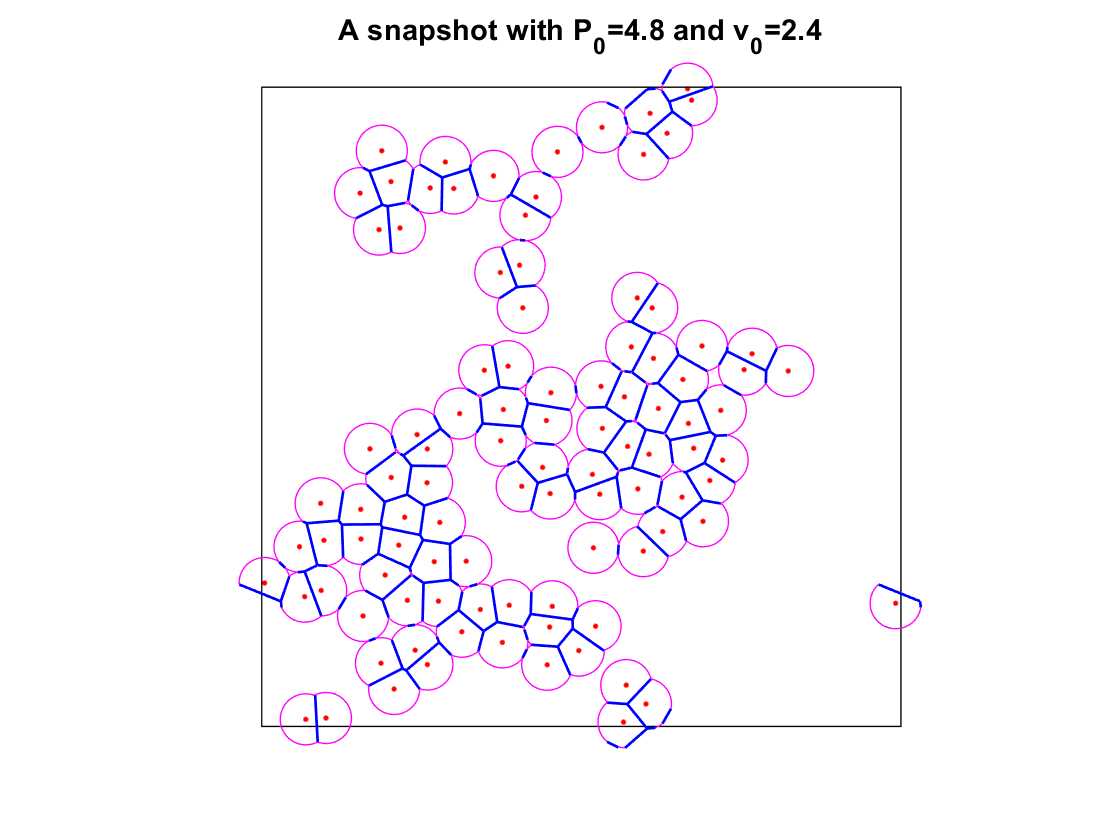

v0_list = [1.2, 2.4];
D_r = 0.1;

for v_idx = 1:2
    v0 = v0_list(v_idx);
    center_xy = center_xy_zero_motility;
    active_angle = rand(N_cell, 1) * 2*pi; % random initialize polarity angle
    
    tic;
    for time = 0:delta_t:10
    
        [cell_chain, edgelist, vertex_position, area_list, perimeter_list] = ...
                    make_finite_voronoi_pbc(center_xy, radius, box_size);
                
        center_force = get_finite_voronoi_force(center_xy, cell_chain, edgelist, ...
    					vertex_position, radius, ones(N_cell, 1), ...
                                            A0_list, K_P, P0_list, tension_difference, ...
                                            area_list, perimeter_list, box_size);
                                        
        active_angle = active_angle + sqrt(2*D_r * delta_t) * randn(N_cell, 1);
        active_force = v0 * [cos(active_angle) sin(active_angle)];
                                  
        center_xy = mod(center_xy + center_force*delta_t + active_force*delta_t, box_size);
              
    end
    toc
    figure, hold on, axis off
    draw_finite_voronoi(cell_chain, edgelist, vertex_position, ...
                        box_size, center_xy, radius)
    title(['A snapshot with P_0=', num2str(P0), ' and v_0=', num2str(v0)])
end

The finite Voronoi configuration information is stored in cell_chain (N lists of edge index indicating the corresponding rows in edgelist), edgelist (the edges could be straight edges or arc edges), and vertex_position (store the vertex/junction position). In addition, the area_list and perimeter_list are both N-by-1 array storing each cell's area and perimeter info.